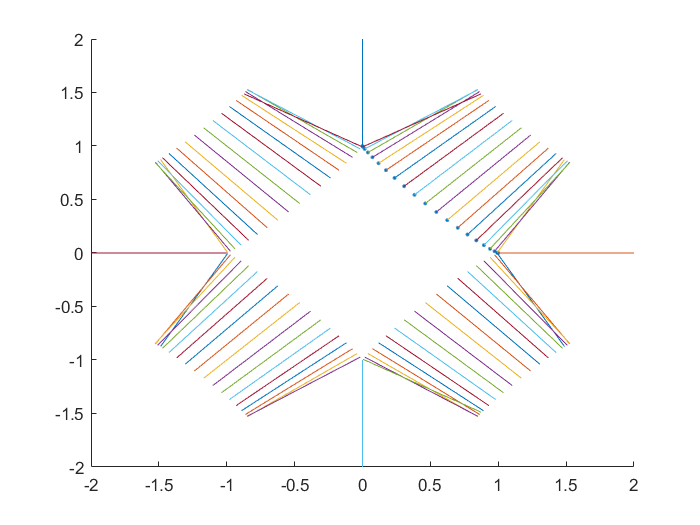

clear;

%超椭圆数据生成
count = 20;
a = 1;
b = 1;
m = 0.9;
theta = 0:(pi/2/count):pi/2;
len = length(theta);
Points = [a*cos(theta').^(2/m), b*sin(theta').^(2/m)];
scatter(Points(:,1),Points(:,2),'.');
hold on;
Gradient = [m/a*Points(:,1).^(m-1),m/b*Points(:,2).^(m-1)];
Gradient(1,:) = Points(1,:);
Gradient(21,:) = Points(21,:);
GradientLen = sqrt(Gradient(:,1).^2+Gradient(:,2).^2);

Gradient = [Gradient(:,1)./GradientLen, Gradient(:,2)./GradientLen,];
Points = [Points(:,1),Points(:,2);-Points(1:20,1),Points(1:20,2)];
Points = [Points(:,1),Points(:,2);Points(2:40,1),-Points(2:40,2)];
Gradient = [Gradient(:,1),Gradient(:,2);-Gradient(1:20,1),Gradient(1:20,2)];
Gradient = [Gradient(:,1),Gradient(:,2);Gradient(2:40,1),-Gradient(2:40,2)];

Normals = Gradient;

for i=1:4*len-4
plot([Points(i,1),Points(i,1)+Gradient(i,1)],[Points(i,2),Points(i,2)+Gradient(i,2)])
end
hold off;

n = 4*length(theta)-4;

k = 5*ones(n,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
% 计算各点支撑半径
SupportSizes = zeros(n,1);
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
% 设置拟合系数
ApproxArgs = 0*ones(n,1);

% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        %Wendland part
        value = rbf_wend(dists(j)/SupportSizes(indices(j)));
        %shepard part
%         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%         if(value==inf)
%             valsum=H(j);
%             rbfsum=1;
%             break;
%         end
        %Our method
%         if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
%             valsum = C(indices(j))+H(j);
%             rbfsum = 1;
%             break;
%         end
%         value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
        
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% 画隐曲线
figure;
f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C));
area = [-1.2,1.2,-1.2,1.2];
fp = fimplicit(f, area);

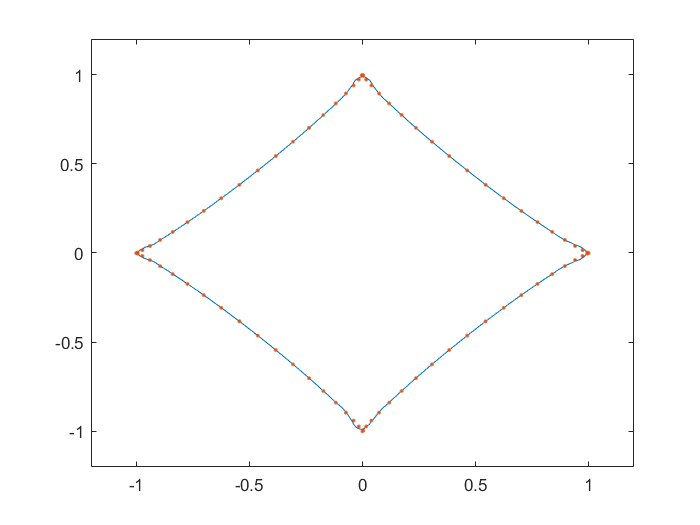

hold on;
scatter(Points(:,1),Points(:,2),'.');
hold off;

% result = [(fp.XData)',(fp.YData)'];

% 画隐曲线
% figure;
% f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C));
% area = [-1,1,-1,1];
% fp = fimplicit(f, area);
% x=-1:0.1:1;
% y=-1:0.1:1;
% [MX,MY]=meshgrid(x,y);
% MZ=zeros(size(MX));
% for i=1:size(MX,1)
%     for j=1:size(MX,2)
%         MZ(i,j)=f(MX(i,j),MY(i,j));
%     end
% end
% surf(x,y,MZ)
% 
% hold on;
% 
% scatter(Points(:,1),Points(:,2),'.');
% hold off;
%result = [(fp.XData)',(fp.YData)'];

% % 计算误差（基于隐函数）
% f = @(x,y)(x.^2+y.^2-1);
% area = [-1.2,1.2,-1.2,1.2];
% res = 1000;
% fp = fimplicit(f, area, 'MeshDensity', res);
% realValue = [(fp.XData)',(fp.YData)'];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)

% % 计算误差（基于参数式）
% res = 10000;
% theta = 0:(2*pi/res):2*pi;
% realValue = [cos(theta)',sin(theta)'];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)

% 计算误差（基于参数式）
% res = 10000;
% theta = 0:(2*pi/res):2*pi;
% realValue = [X,Y];
% kdtree = KDTreeSearcher(realValue);
% error = zeros(size(result,1),1);
% for i=1:size(result,1)
%     [indice,error(i)]=knnsearch(kdtree, result(i,:), 'K', 1);
% end
% max(error)
